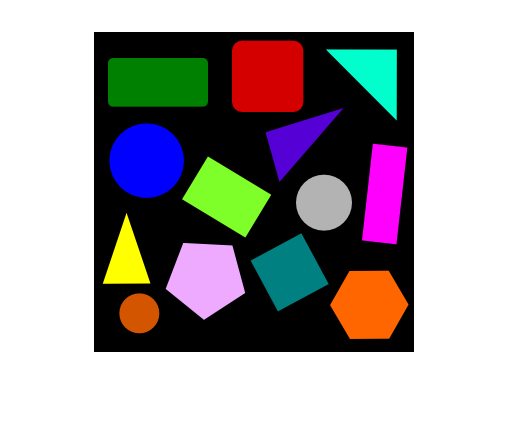

pic = imread('objects.png');
imshow(pic);

s = im2double(pic);

x = im2bw(s);


Black and white image

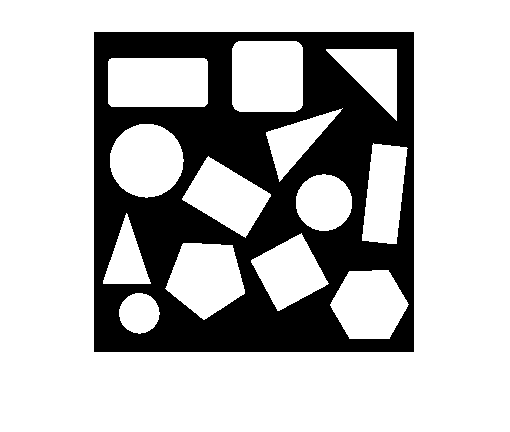

bw = imcomplement(pic);
bw= im2bw(bw,230/255);
bw=imcomplement(bw);
imshow(bw);


% SE = strel('disk',10);
% B=imclose(bw,SE)
% B= imcomplement(B)
% imshow(B)

finding centroid 

s = regionprops(bw, 'all')

s = 13×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates


R = regionprops(bw, 'Centroid')

R = 13×1 struct array with fields:
    Centroid


position

for i = 1:length(s)
 center = R(i).Centroid;
 disp([num2str(i), ': Position = (', num2str(center(1)), ',',num2str(center(2)), ')']);
end

1: Position = (33.1176,228.4261)
2: Position = (64.5,50.9906)
3: Position = (53.177,129.1707)
4: Position = (45.8132,281.8132)
5: Position = (112.5835,246.5321)
6: Position = (133.1573,165.4931)
7: Position = (174.0278,44.9722)
8: Position = (196.1482,240.848)
9: Position = (202.7018,109.2882)
10: Position = (230.5,171.1775)
11: Position = (279.3514,41.6757)
12: Position = (275.8645,273.3077)
13: Position = (291.1554,162.493)


red outline

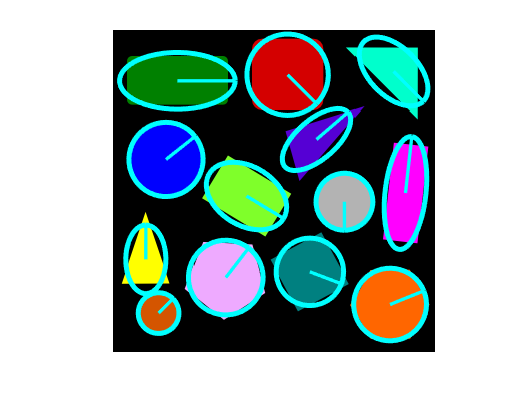

figure
imshow(pic,'InitialMagnification','fit')
t = linspace(0,2*pi,50);
px = cell(1,length(s));
py=cell(1,length(s));

hold on
for k = 1:length(s)
    a = s(k).MajorAxisLength/2;
    b = s(k).MinorAxisLength/2;
    Xc = s(k).Centroid(1);
    Yc = s(k).Centroid(2);
%     px{k}=[yc];
%     py{k}=[xc];
    phi = deg2rad(-s(k).Orientation);
    x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
    y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
    plot(x,y,'cyan','Linewidth',3);
    ex = a*cos(phi) + Xc;
    ey = a*sin(phi) + Yc;
    plot([Xc,ex], [Yc,ey], 'cyan', 'LineWidth', 2);
%     Rz = [cosd(s(i).Orientation) -sind(s(i).Orientation) ; sind(s(i).Orientation) cosd(s(i).Orientation) ];
%     new_p = Rz*[ex;ey]+[Xc;Yc]
    
end
hold off

rotating the i

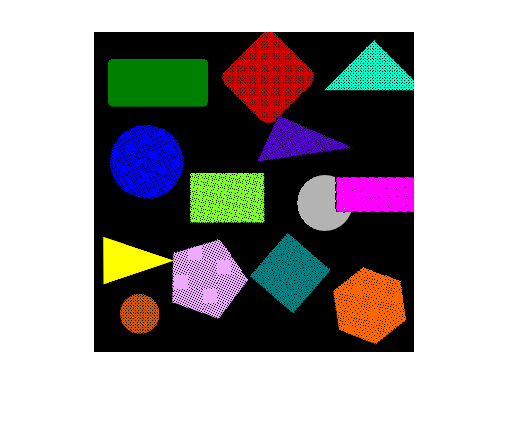

stats = regionprops(bw,{'Centroid','MajorAxisLength','MinorAxisLength','Orientation','pixelIdxList'});

new_image = pic; % Initiating a new image
new_image(:,:,:) = 0; % With RGB = black background
for i = 1:length(s)
 centroid = stats(i).Centroid; % centeroid of each object
 orientation = -stats(i).Orientation; % oreintation of each object
 Pixel_Index_List = stats(i).PixelIdxList; %Pixcel Index list of each object
 R_z = [cosd(orientation), -sind(orientation), 0;
 sind(orientation), cosd(orientation), 0;
 0, 0, 1]; % Rotation Matrix around z-axis:
 T_f = [cosd(orientation), -sind(orientation), 0, 0;
 sind(orientation), cosd(orientation), 0, 0;
 0, 0, 1, 0;
 0, 0, 0, 1]; %Transformation matrix
 % finding each point of the object
 for j = 1: length(Pixel_Index_List)
 x = mod(Pixel_Index_List(j), 320) + 1;
 y = ceil(Pixel_Index_List(j) / 320);
 % shifting each point (x, y) to the origin
 shifted_x = x - centroid(2);
 shifted_y = y - centroid(1);
 % Rotating object at transformation T_f
 P_a = [shifted_x; shifted_y; 0 ; 1];
 P_b = T_f*P_a;
 % Shifting object back to its previous position
 new_x = P_b(1) + centroid(2);
 new_y = P_b(2) + centroid(1);

 % we have to limit the boundary to the image pixcels
 if ((new_x>0 && new_x<320) && (new_y>0 && new_y<320))
 % RGB
 new_image(ceil(new_x), ceil(new_y),1) = pic(x,y, 1);
 new_image(ceil(new_x), ceil(new_y),2) = pic(x,y, 2);
 new_image(ceil(new_x), ceil(new_y),3) = pic(x,y, 3);
 end
 end
end
imshow(new_image)